clear all, close all, clc

% Floating Base Inverse Kinematics for a 4-legged Robot
% Assumptions:
% - Each leg has 2 DOF (hip and knee)
% - The base is a rigid body in 3D space (floating base)
% - Leg kinematics are planar (2D per leg)

l1 = 4; % link 1
l2 = 6.3; % link 2
L_b = 12; % Lenght base
W_b = 10; % wight base
H_b = 0.2; % higth base
x = 0;
z = -9;

base_corners = [           % Base corners for each leg
    L_b/2,W_b/2,-H_b/2;    % ULL
    L_b/2,-W_b/2,-H_b/2;   % URL
    -L_b/2,W_b/2,-H_b/2;   % LLL
    -L_b/2,-W_b/2,-H_b/2   % LRL
];

% Test
[q1_ULL, q2_ULL] = legIK(x, z, l1, l2)

q1_ULL = 0.5715

q2_ULL = 1.3937

[q1_URL, q2_URL] = legIK(x, z, l1, l2)

q1_URL = 0.5715

q2_URL = 1.3937

[q1_LLL, q2_LLL] = legIK(x, z, l1, l2)

q1_LLL = 0.5715

q2_LLL = 1.3937

[q1_LRL, q2_LRL] = legIK(x, z, l1, l2)

q1_LRL = 0.5715

q2_LRL = 1.3937

## Test

% Robot Parameters
l1 = 4; l2 = 6.3;              % Link lengths
link_lengths = [l1, l2];     % Vector of link lengths
L_b = 12; % Lenght base
W_b = 10; % wight base
H_b = 0; % higth base

leg_origins = [              % Each row is origin of a leg in body frame
    L_b/2,  W_b/2, 0;   % ULL
    L_b/2, -W_b/2, 0;   % URL
   -L_b/2,  W_b/2, 0;   % LLL
   -L_b/2, -W_b/2, 0    % LRL
];

% Desired base pose in world
xyz_base = [0; 0; 7.5];                    % 1 meter above ground
rpy_base = deg2rad([0, 0, 0]);           % No rotation

% Desired foot positions in world (feet on the ground)
foot_world_targets = [                   % Each column is a foot position in world
    L_b/2;  W_b/2; 0;   % ULL
    L_b/2; -W_b/2; 0;   % URL
   -L_b/2;  W_b/2; 0;   % LLL
   -L_b/2; -W_b/2; 0    % LRL
];
foot_world_targets = reshape(foot_world_targets, 3, 4);
% foot_world_targets first is a 4x3 matrix and after reshape is a 3x4
% matrix

% Solve IK for each leg

Q = zeros(4,2); % Creating a matrix for Q values
for legID = 1:4
    xyz_foot = foot_world_targets(:,legID);
    [angles] = ik_leg_floating(xyz_foot, rpy_base, legID, leg_origins, xyz_base, link_lengths);
    Q(legID,:) = angles;

    %[angles] = liying();
    %Q(legID,:) = angles;
end


## Plot

P0 =      0
     0
     0


P_TOTAL =          0    6.0000    6.0000    2.2412    2.2412    8.5412
         0    5.0000    5.0000    5.0000    5.0000    5.0000
         0   -0.1000   -0.1000   -1.4681   -1.4681   -1.4681


P0 =      0
     0
     0


P_TOTAL =          0    6.0000    6.0000    2.2412    2.2412    8.5412
         0   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000
         0   -0.1000   -0.1000   -1.4681   -1.4681   -1.4681


P0 =      0
     0
     0


P_TOTAL =          0   -6.0000   -6.0000   -9.7588   -9.7588   -3.4588
         0    5.0000    5.0000    5.0000    5.0000    5.0000
         0   -0.1000   -0.1000   -1.4681   -1.4681   -1.4681


P0 =      0
     0
     0


P_TOTAL =          0   -6.0000   -6.0000   -9.7588   -9.7588   -3.4588
         0   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000
         0   -0.1000   -0.1000   -1.4681   -1.4681   -1.4681


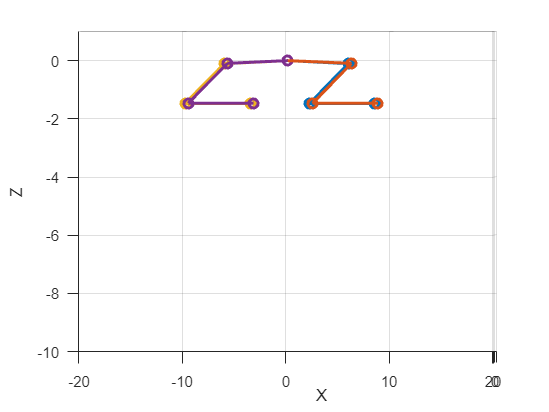

close all
for i=1:4
    I = eye(3); % Matriz identidad
    p = [0;0;0]; % No traslación
    
    % Posición inicial
    p_inicial = [0;0;0]; % No traslación
    
    % De 0 con respecto a la base
    R0_b = RotX(-pi/2)*RotY(pi);
    p0_b = [base_corners(i,1);base_corners(i,2);base_corners(i,3)];
    T0_b = Transform(R0_b, p0_b);
    
    % De 1 con respecto 0
    
    R1_0 = RotZ(Q(i,1)+pi/9);
    T1_0 = Transform(R1_0, p);
    
    % De 2 con respecto 1
    
    p2_1 = [l1;0;0];
    T2_1 = Transform(I, p2_1);
    
    % De 3 con respecto 2
    
    R3_2 = RotZ(Q(i,2)-pi/9);
    T3_2 = Transform(R3_2, p);
    
    % De 4 con respecto 3
    
    p4_3 = [l2;0;0];
    T4_3 = Transform(I, p4_3);
    
    % De 4 con respecto a la base
    T4_b = T0_b*T1_0*T2_1*T3_2*T4_3;

    % Tranformaciones por puntos
    T1_b = T0_b*T1_0;
    T2_b = T1_b*T2_1;
    T3_b = T2_b*T3_2;
    
    P0 = p_inicial
    P1 = [T0_b(1,4);T0_b(2,4);T0_b(3,4)];
    P2 = [T1_b(1,4);T1_b(2,4);T1_b(3,4)];
    P3 = [T2_b(1,4);T2_b(2,4);T2_b(3,4)];
    P4 = [T3_b(1,4);T3_b(2,4);T3_b(3,4)];
    P5 = [T4_b(1,4);T4_b(2,4);T4_b(3,4)];

    P_TOTAL = [P0,P1,P2,P3,P4,P5] % [X;Y;Z]
    plot3(P_TOTAL(1,:), P_TOTAL(2,:), P_TOTAL(3,:), '-o', 'LineWidth', 2, 'MarkerSize', 6);
    hold on;
    grid on;
    xlabel('X'), ylabel('Y'), zlabel('Z')
    xlim([-20 20]), ylim([-6 6]), zlim([-10 1]);
end

## Plot 2

figure;
hold on;
axis equal;
grid on;
% xlabel('X'); ylabel('Y'); zlabel('Z');
% title('Quadruped Leg IK Visualization');

% Plot base orientation using quiver3
R_base = eul2rotm(rpy_base, 'XYZ');
quiver3(xyz_base(1), xyz_base(2), xyz_base(3), R_base(1,1), R_base(2,1), R_base(3,1), 0.5, 'r', 'LineWidth', 2); % X
quiver3(xyz_base(1), xyz_base(2), xyz_base(3), R_base(1,2), R_base(2,2), R_base(3,2), 0.5, 'g', 'LineWidth', 2); % Y
quiver3(xyz_base(1), xyz_base(2), xyz_base(3), R_base(1,3), R_base(2,3), R_base(3,3), 0.5, 'b', 'LineWidth', 2); % Z

colors = {'m', 'c', 'k', 'y'}; % Colors for the 4 legs

Q_real = [0 0;0 0;0 0;0 0];

for legID = 1:4
    % Get origin of leg in world frame
    origin_body = leg_origins(legID, :)';        % in body frame
    origin_world = R_base * origin_body + xyz_base; % rotated and translated

    % Joint angles
    q1 = Q(legID, 1);
    q2 = Q(legID, 2);

    Q_real(legID,1) = q1
    Q_real(legID,2) = abs(q2-pi)
       
    if legID == 1 || legID == 3
        Q_real(legID,1) = Q_real(legID,1);
        Q_real(legID,2) = Q_real(legID,2);
    elseif legID == 2 || legID == 4
        Q_real(legID,1) = abs(Q_real(legID,1)-pi);
        Q_real(legID,2) = abs(Q_real(legID,2)-pi);
    end

    q1 = q1+pi/9;
    q2 = q2-pi/9;

    % Forward kinematics in leg frame (X-Z)
    joint1_leg = [0; 0; 0];
    joint2_leg = [-l1*cos(q1); 0; -l1*sin(q1)];
    foot_leg    = joint2_leg + [-l2*cos(q1 + q2); 0; -l2*sin(q1 + q2)];

    % Rotate leg frame to world frame
    joint2_world = R_base * joint2_leg + origin_world;
    foot_world = R_base * foot_leg + origin_world;

    % Plot leg segments
    plot3([origin_world(1), joint2_world(1)], ...
          [origin_world(2), joint2_world(2)], ...
          [origin_world(3), joint2_world(3)], ...
          'Color', colors{legID}, 'LineWidth', 2);

    plot3([joint2_world(1), foot_world(1)], ...
          [joint2_world(2), foot_world(2)], ...
          [joint2_world(3), foot_world(3)], ...
          'Color', colors{legID}, 'LineWidth', 2);
end

Q_real =     0.2245         0
         0         0
         0         0
         0         0


Q_real =     0.2245    1.2328
         0         0
         0         0
         0         0


Q_real =     0.2245    1.2328
    0.2245         0
         0         0
         0         0


Q_real =     0.2245    1.2328
    0.2245    1.2328
         0         0
         0         0


Q_real =     0.2245    1.2328
    2.9170    1.9088
    0.2245         0
         0         0


Q_real =     0.2245    1.2328
    2.9170    1.9088
    0.2245    1.2328
         0         0


Q_real =     0.2245    1.2328
    2.9170    1.9088
    0.2245    1.2328
    0.2245         0


Q_real =     0.2245    1.2328
    2.9170    1.9088
    0.2245    1.2328
    0.2245    1.2328


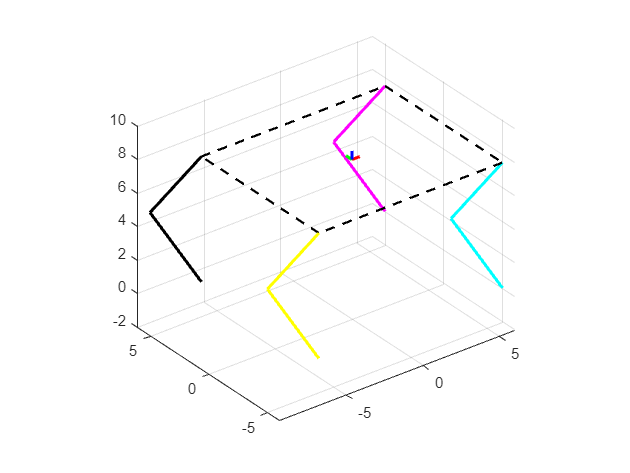


% Compute leg origins in world frame (after rotation and translation)
origins_world = zeros(3, 4);
for legID = 1:4
    origin_body = leg_origins(legID, :)';        % in body frame
    origin_world = R_base * origin_body + xyz_base;
    origins_world(:, legID) = origin_world;
end

% Plot the body rectangle (connect the 4 origins)
% Define connection order: ULL → URL → LRL → LLL → ULL
connection_order = [1, 2, 4, 3, 1];

for i = 1:length(connection_order)-1
    p1 = origins_world(:, connection_order(i));
    p2 = origins_world(:, connection_order(i+1));
    plot3([p1(1), p2(1)], [p1(2), p2(2)], [p1(3), p2(3)], 'k--', 'LineWidth', 1.5);
end
view(3);

## Animation

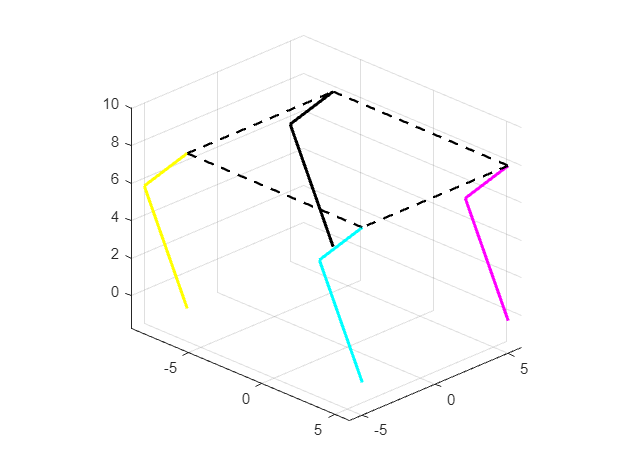

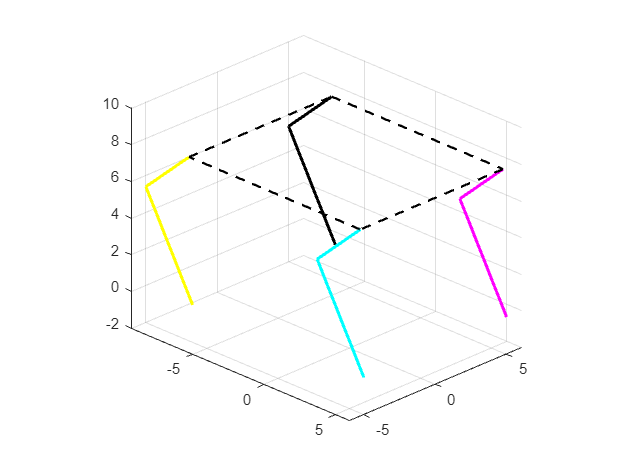

% Animation: Move base up and down while feet stay fixed
z_amplitude = 1.5;           % Amplitude of vertical motion
z_center = 8;              % Initial Z height
x_amplitude = 2;           % Amplitude of horizontal motion
x_center = 0;              % Initial X height
pitch_amplitude = 10;           % Amplitude of pitch orientation
pitch_center = 0;              % Initial pitch angle

n_frames = 100;              % Number of frames
fps = 30;                    % Frame rate

% Prepare figure
figure;
axis equal;
grid on;
%xlabel('X'); ylabel('Y'); zlabel('Z');
%title('Quadruped Base Up and Down Animation');
view(45, 25); % azimuth 45°, elevation 25° (example)
%view(3);

for k = 1:n_frames
    clf; % Clear figure
    hold on;
    axis equal;
    grid on;
    %xlabel('X'); ylabel('Y'); zlabel('Z');
    %title('Quadruped Base Up and Down Animation');
    view(45, 25); % azimuth 45°, elevation 25° (example)
    
    
    % Time phases
    if k <= n_frames/3
        % Phase 1: Z motion only
        z_base = z_center + z_amplitude * sin(2*pi*k/(n_frames/3));
        x_base = 0;
        pitch_base = 0;
    elseif k <= 2*n_frames/3
        % Phase 2: X motion only
        z_base = z_center;
        x_base = x_center + x_amplitude * sin(2*pi*(k - n_frames/3)/(n_frames/3));
        pitch_base = 0;
    else
        % Phase 3: Pitch rotation only
        pitch_base = pitch_center + pitch_amplitude * sin(2*pi*(k - 2*n_frames/3)/(n_frames/3));
    end
    
    xyz_base = [x_base; 0; z_base];
    rpy_base = deg2rad([0, pitch_base, 0]);
    R_base = eul2rotm(rpy_base, 'XYZ');

    % Solve IK for each leg
    Q = zeros(4,2);
    for legID = 1:4
        xyz_foot = foot_world_targets(:,legID);
        Q(legID,:) = ik_leg_floating(xyz_foot, rpy_base, legID, leg_origins, xyz_base, link_lengths);
    end

    % % Plot base orientation
    % quiver3(xyz_base(1), xyz_base(2), xyz_base(3), R_base(1,1), R_base(2,1), R_base(3,1), 0.5, 'r', 'LineWidth', 2);
    % quiver3(xyz_base(1), xyz_base(2), xyz_base(3), R_base(1,2), R_base(2,2), R_base(3,2), 0.5, 'g', 'LineWidth', 2);
    % quiver3(xyz_base(1), xyz_base(2), xyz_base(3), R_base(1,3), R_base(2,3), R_base(3,3), 0.5, 'b', 'LineWidth', 2);

    % Plot all legs
    for legID = 1:4
        origin_body = leg_origins(legID, :)';
        origin_world = R_base * origin_body + xyz_base;

        q1 = Q(legID, 1);
        q2 = Q(legID, 2);

        q1 = q1+pi/9;
        q2 = q2-pi/9;
    
        % Forward kinematics in leg frame (X-Z)
        joint1_leg = [0; 0; 0];
        joint2_leg = [-l1*cos(q1); 0; -l1*sin(q1)];
        foot_leg    = joint2_leg + [-l2*cos(q1 + q2); 0; -l2*sin(q1 + q2)];

        joint2_world = R_base * joint2_leg + origin_world;
        foot_world = R_base * foot_leg + origin_world;

        plot3([origin_world(1), joint2_world(1)], ...
              [origin_world(2), joint2_world(2)], ...
              [origin_world(3), joint2_world(3)], ...
              'Color', colors{legID}, 'LineWidth', 2);

        plot3([joint2_world(1), foot_world(1)], ...
              [joint2_world(2), foot_world(2)], ...
              [joint2_world(3), foot_world(3)], ...
              'Color', colors{legID}, 'LineWidth', 2);
    end

    % Plot base rectangle
    origins_world = zeros(3, 4);
    for legID = 1:4
        origin_body = leg_origins(legID, :)';
        origin_world = R_base * origin_body + xyz_base;
        origins_world(:, legID) = origin_world;
    end

    connection_order = [1, 2, 4, 3, 1];
    for i = 1:length(connection_order)-1
        p1 = origins_world(:, connection_order(i));
        p2 = origins_world(:, connection_order(i+1));
        plot3([p1(1), p2(1)], [p1(2), p2(2)], [p1(3), p2(3)], 'k--', 'LineWidth', 1.5);
    end

    %legend({'Base X','Base Y','Base Z'}, 'Location', 'northeast');
    drawnow;
    pause(1/fps);
end

## inverse kinematic

function [q1, q2] = legIK(x, z, l1, l2)
    r = sqrt(x^2 + z^2);
    cos_theta2 = (r^2 - l1^2 - l2^2)/(2*l1*l2);
    sin_theta2 = sqrt(1 - cos_theta2^2);  % Choose elbow-down
    theta2 = atan2(sin_theta2, cos_theta2);
    
    phi = atan2(-z, -x);
    beta = atan2(l2*sin_theta2, l1 + l2*cos_theta2);
    theta1 = phi - beta;
    
    % Recover joint angles
    q1 = theta1 - pi/9;
    q2 = theta2 + pi/9;

end

%% Inverse kinematic with floating base

function [angles] = ik_leg_floating(xyz_foot_world, rpy_base, legID, leg_origins, xyz_base, link_lengths)
    % xyz_foot_world: posición deseada del pie en el mundo [x;y;z]
    % rpy_base: orientación del cuerpo [roll; pitch; yaw] en radianes
    % legID: índice de la pierna (1 a 4)
    % leg_origins: matriz 4x3 con los orígenes de las piernas en el cuerpo
    % xyz_base: posición del cuerpo (flotante) en el mundo
    % link_lengths: [L1, L2]

    % Rotación del cuerpo
    R = eul2rotm(rpy_base, 'XYZ');

    % Origen de la pierna en el mundo (considerando rotación y posición del cuerpo)
    origin_leg_world = R * leg_origins(legID, :)' + xyz_base;

    % Posición del pie respecto al origen de la pierna
    p_leg = xyz_foot_world - origin_leg_world;

    % Solo usamos el plano X-Z para la cinemática inversa de 2 DOF
    x = p_leg(1);
    z = p_leg(3);

    % Extraer longitudes
    L1 = link_lengths(1);
    L2 = link_lengths(2);

    % Usar tu función personalizada
    [q1, q2] = legIK(x, z, L1, L2);

    angles = [q1; q2];
end


## Homogenious transformation

function R = RotZ(theta)
    R = [cos(theta), -sin(theta), 0;
         sin(theta),  cos(theta), 0;
               0,           0,    1];
end

function R = RotY(theta)
    R = [cos(theta),  0, sin(theta);
             0,       1,     0;
        -sin(theta), 0, cos(theta)];
end

function R = RotX(theta)
    R = [1,      0,           0;
         0, cos(theta), -sin(theta);
         0, sin(theta),  cos(theta)];
end

%% Homogeneus transformation

function T = Transform(R, p)
    T = [R, p(:); 0 0 0 1];
end


## Actions

% lift a leg


% liying
function [angles] = liying()

    angles = [0 pi];

end